%% Simulación Comparativa de 4 Muestras de Células DSSC
% Efecto acoplado: Reflectividad (Jsc) y Resistencia Serie (FF) simultáneamente.
clear; clc; close all;

%% 1. CONFIGURACIÓN DE LAS MUESTRAS (EDITAR AQUÍ)
% Define aquí los nombres y propiedades de tus 4 muestras
% -------------------------------------------------------------------------
Nombres = {'Maestra 1 ', ...  % Nombre 1
           'Maestra 2', ...    % Nombre 2
           'Maestra 3', ...      % Nombre 3
           'Maestra 4'};          % Nombre 4

% Reflectividad del Contraelectrodo (0.0 a 1.0)
% [Muestra 1, Muestra 2, Muestra 3, Muestra 4]
Reflectividades = [0.2677, 0.1948, 0.1783, 0.14645]; 

% Resistencia del Contraelectrodo en Ohms (Afecta al FF)
% [Muestra 1, Muestra 2, Muestra 3, Muestra 4]
Resistencias_CE = [2.36e-9, 2.30e-9, 5.82e-9, 1.5e-9]; 
% -------------------------------------------------------------------------

%% 2. CONSTANTES FÍSICAS Y PARÁMETROS FIJOS
q = 1.60217662e-19;    % Carga elemental
k_B = 1.38064852e-23;  % Boltzmann
T = 300;               % Temperatura (K)
Vt = (k_B * T) / q;    % Voltaje térmico
Area = 1.0;            % cm^2
P_in = 100e-3;         % 100 mW/cm^2 (1 Sun)

% Parámetros del Fotoánodo (Constantes para todas)
alpha = 1500;          % Coef. absorción [cm^-1]
d = 12e-4;             % Espesor [cm]
T_glass = 0.9;         % Transmitancia del vidrio FTO
R_sh = 5000;           % Resistencia Shunt (alta calidad)
J0 = 5e-7;             % Corriente de saturación oscura
n_id = 2.5;            % Factor de idealidad
R_s_base = 1;          % Resistencia base (FTO+Electrolito) sin el CE
J_max_pot = 22e-3;     % Corriente máx teórica (si absorbiera 100%)

% Vector de Voltaje
V = 0:0.005:1.0; 

%% 3. FUNCIÓN DE CÁLCULO (Lambert W)
% Solver explícito para la corriente I
calc_I = @(V, Iph, Rs, Rsh, n, I0, Vt) ...
    (Rsh*(Iph + I0) - V) ./ (Rs + Rsh) - ...
    (n*Vt ./ Rs) .* lambertw( ...
        (Rs .* I0 .* Rsh) ./ (n*Vt * (Rs + Rsh)) .* ...
        exp((Rsh .* (Rs.*(Iph + I0) + V)) ./ (n*Vt * (Rs + Rsh))) ...
    );

%% 4. BUCLE DE SIMULACIÓN Y GRAFICADO
figure('Name', 'Comparativa de Muestras DSSC', 'Color', 'w', 'Position', [100, 100, 900, 600]);
hold on; grid on;
colores = [0.85, 0.00, 0.00;  % 1. Rojo Profundo (Muestra A)
    1.00, 0.25, 0.00;  % 2. Rojo Anaranjado (Muestra B)
    1.00, 0.50, 0.00;  % 3. Naranja Puro (Muestra C)
    1.00, 0.75, 0.00]   % 4. Ámbar / Naranja Claro (Muestra D)

colores =     0.8500         0         0
    1.0000    0.2500         0
    1.0000    0.5000         0
    1.0000    0.7500         0



leyenda_texto = {}; % Para guardar los nombres de la leyenda
plot_handles = [];  % Para guardar los punteros de las líneas principales

fprintf('--- RESULTADOS DE SIMULACIÓN ---\n');

--- RESULTADOS DE SIMULACIÓN ---


fprintf('%-20s | Jsc (mA) | Voc (V) | FF (%%) | Eta (%%)\n', 'Muestra');

Muestra              | Jsc (mA) | Voc (V) | FF (%) | Eta (%)


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



for i = 1:4
    % A. Obtener parámetros de la muestra actual
    R_opt = Reflectividades(i);
    R_elec = Resistencias_CE(i);
    Nombre = Nombres{i};
    Color = colores(i,:);
    
    % B. Modelo Óptico: Calcular Jph específica
    % Transmitancia de un paso por el TiO2
    T_pass = exp(-alpha * d); 
    % LHE = Absorción directa + (Transmitida * Reflejada * Re-absorbida)
    LHE = (1 - T_pass) + (T_pass * R_opt * (1 - T_pass));
    J_ph = J_max_pot * LHE;
    
    % C. Modelo Eléctrico: Calcular Rs total
    Rs_total = R_s_base + R_elec;
    
    % D. Calcular Curva I-V
    I_curve = calc_I(V, J_ph, Rs_total, R_sh, n_id, J0, Vt);
    
    % E. Encontrar Punto de Máxima Potencia (MPP) y Voc
    Power = V .* I_curve;
    [P_max, idx_mpp] = max(Power);
    V_mp = V(idx_mpp);
    I_mp = I_curve(idx_mpp);
    
    % Encontrar Voc (donde la corriente cruza 0)
    [~, idx_voc] = min(abs(I_curve));
    V_oc = V(idx_voc);
    J_sc = I_curve(1); % A V=0
    
    % Calcular Métricas
    FF = P_max / (V_oc * J_sc);
    Eta = (P_max / P_in) * 100; % Eficiencia
    
    % F. Imprimir resultados en consola
    fprintf('%-20s | %8.2f | %7.3f | %6.1f | %7.2f\n', ...
        Nombre, J_sc*1000, V_oc, FF*100, Eta);
    
    % G. GRAFICAR
    % 1. La Curva I-V principal
    h = plot(V, I_curve*1000, 'LineWidth', 2.5, 'Color', Color);
    plot_handles = [plot_handles, h]; % Guardar para leyenda
    
    % Construir texto para leyenda
    leyenda_texto{end+1} = sprintf('%s (\\eta=%.2f%%)', ...
                                   Nombre, Eta);
    
    % 2. El Rectángulo de FF (Sombreado)
    % Coordenadas: (0,0) -> (Vmp, 0) -> (Vmp, Imp) -> (0, Imp)
    X_fill = [0, V_mp, V_mp, 0];
    Y_fill = [0, 0, I_mp*1000, I_mp*1000];
    fill(X_fill, Y_fill, Color, 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    
    % 3. Punto MPP
    plot(V_mp, I_mp*1000, 'o', 'MarkerFaceColor', Color, 'MarkerEdgeColor', 'k', 'HandleVisibility', 'off');
    
    % 4. Línea punteada del rectángulo (opcional, para definir borde)
    plot([V_mp, V_mp], [0, I_mp*1000], '--', 'Color', Color, 'LineWidth', 1, 'HandleVisibility', 'off');
    plot([0, V_mp], [I_mp*1000, I_mp*1000], '--', 'Color', Color, 'LineWidth', 1, 'HandleVisibility', 'off');
end

Maestra 1            |    19.17 |   0.680 |   68.0 |    8.86
Maestra 2            |    18.95 |   0.680 |   67.9 |    8.75
Maestra 3            |    18.90 |   0.680 |   67.9 |    8.72
Maestra 4            |    18.80 |   0.680 |   67.8 |    8.67


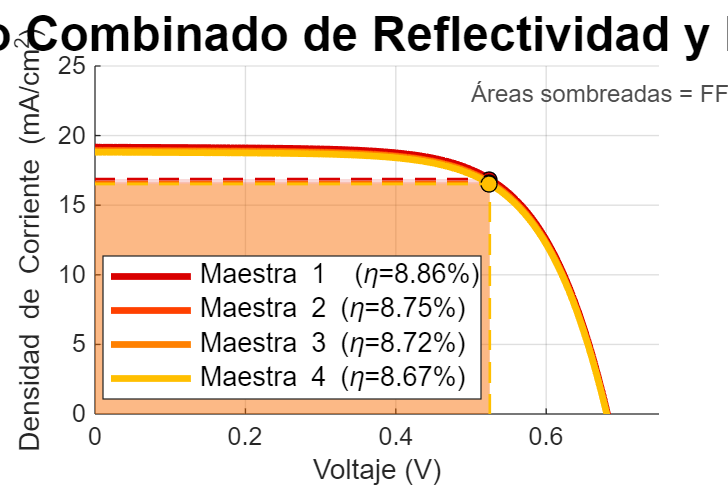


% Ajustes finales del gráfico
title('Curvas I-V: Efecto Combinado de Reflectividad y Resistencia del CE','FontSize', 18);
xlabel('Voltaje (V)');
ylabel('Densidad de Corriente (mA/cm^2)');
xlim([0 0.75]);
ylim([0 25]); % Ajustar según tus J_max
legend(plot_handles, leyenda_texto, 'Location', 'best', 'FontSize', 10);

% Anotación explicativa
text(0.5, 23, 'Áreas sombreadas = FF', 'FontSize', 9, 'Color', [0.3 0.3 0.3]);